clearvars; close all; clc;

%load signal
load('ECGsig.mat')

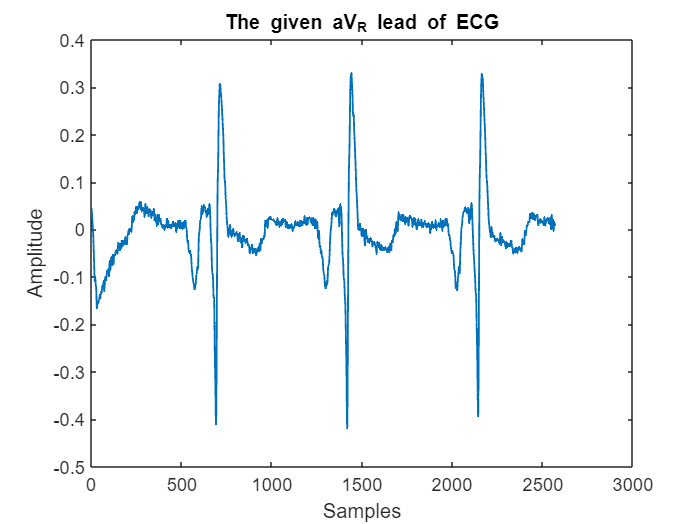

%Plot the aVR signal
figure;
plot(aVR, 'LineWidth',1);
title('The given aV_R lead of ECG');
xlabel('Samples');
ylabel('Amplitude');

% Obtain wavelet coefficients
[coeffs_db9, l_db9] = wavedec(aVR, 10, 'db9'); % db9 wavelet
[coeffs_haar, l_haar] = wavedec(aVR, 10, 'haar'); % haar wavelet

% Arrange coefficients in descending order
sorted_coeffs_db9 = sort(abs(coeffs_db9), 'descend');
sorted_coeffs_haar = sort(abs(coeffs_haar), 'descend');

% Calculate total energy of the coefficients
total_energy_db9 = sum(sorted_coeffs_db9.^2);
total_energy_haar = sum(sorted_coeffs_haar.^2);

% Display the total energy values
fprintf('Total Energy of db9 Coefficients: %.4f\n', total_energy_db9);

Total Energy of db9 Coefficients: 17.9618


fprintf('Total Energy of Haar Coefficients: %.4f\n', total_energy_haar);

Total Energy of Haar Coefficients: 15.7709



disp(['Number of coefficients (db9): ', num2str(length(coeffs_db9))]);

Number of coefficients (db9): 2733


disp(['Number of coefficients (Haar): ', num2str(length(coeffs_haar))]);

Number of coefficients (Haar): 2577


% Calculate cumulative energy
cumulative_energy_db9 = cumsum(sorted_coeffs_db9.^2);
cumulative_energy_haar = cumsum(sorted_coeffs_haar.^2);

% Find the number of coefficients needed to represent 99% of the energy
threshold_db9 = 0.99 * total_energy_db9;
threshold_haar = 0.99 * total_energy_haar;

num_coeffs_db9 = find(cumulative_energy_db9 >= threshold_db9, 1);
num_coeffs_haar = find(cumulative_energy_haar >= threshold_haar, 1);

disp(['Number of coefficients (db9) for 99% energy: ', num2str(num_coeffs_db9)]);

Number of coefficients (db9) for 99% energy: 170


disp(['Number of coefficients (Haar) for 99% energy: ', num2str(num_coeffs_haar)]);

Number of coefficients (Haar) for 99% energy: 177


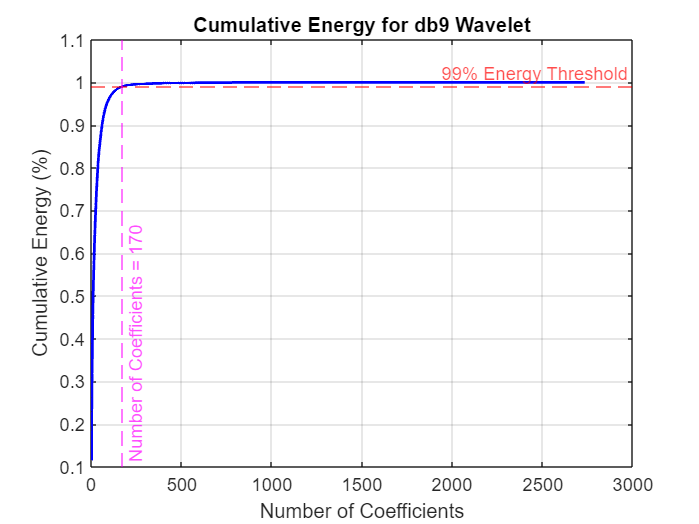

% Plot cumulative energy for db9
figure;
plot(cumulative_energy_db9 / total_energy_db9, 'b-', 'LineWidth', 1.5); % Normalizing for percentage 
hold on;
yline(0.99, 'r--', '99% Energy Threshold'); % Horizontal line for 99% threshold
xline(num_coeffs_db9, 'm--', 'Number of Coefficients = 170', 'LabelVerticalAlignment', 'bottom'); % Vertical line for number of coefficients
xlabel('Number of Coefficients');
ylabel('Cumulative Energy (%)');
title('Cumulative Energy for db9 Wavelet');
grid on;
hold off;

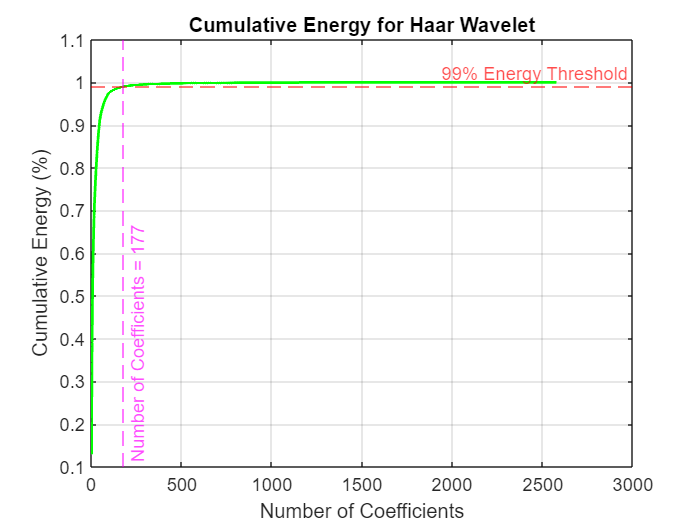


% Plot cumulative energy for Haar
figure;
plot(cumulative_energy_haar / total_energy_haar, 'g-', 'LineWidth', 1.5); % Normalizing for percentage
hold on;
yline(0.99, 'r--', '99% Energy Threshold'); % Horizontal line for 99% threshold
xline(num_coeffs_haar, 'm--', 'Number of Coefficients = 177', 'LabelVerticalAlignment', 'bottom'); % Vertical line for number of coefficients
xlabel('Number of Coefficients');
ylabel('Cumulative Energy (%)');
title('Cumulative Energy for Haar Wavelet');
grid on;
hold off;

#### Compress the signal

% Set insignificant coefficients to zero (for db9 and haar)
coeffs_db9_compressed = coeffs_db9;
coeffs_haar_compressed = coeffs_haar;

coeffs_db9_compressed(abs(coeffs_db9_compressed) < sorted_coeffs_db9(num_coeffs_db9)) = 0; % Zero out for db9
coeffs_haar_compressed(abs(coeffs_haar_compressed) < sorted_coeffs_haar(num_coeffs_haar)) = 0; % Zero out for haar

% Reconstruct signals from compressed coefficients
reconstructed_db9 = waverec(coeffs_db9_compressed, l_db9, 'db9');
reconstructed_haar = waverec(coeffs_haar_compressed, l_haar, 'haar');

% Calculate compression ratios
compression_ratio_db9 = length(coeffs_db9) / num_coeffs_db9;
compression_ratio_haar = length(coeffs_haar) / num_coeffs_haar;

% Display compression ratios
fprintf('Compression Ratio (db9): %.2f\n', compression_ratio_db9);

Compression Ratio (db9): 16.08


fprintf('Compression Ratio (Haar): %.2f\n', compression_ratio_haar);

Compression Ratio (Haar): 14.56


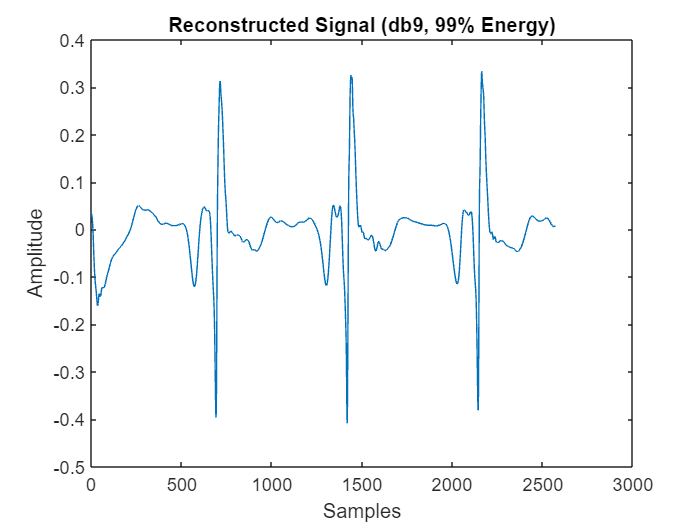


% Plot the original and reconstructed signals
figure;
plot(reconstructed_db9);
title('Reconstructed Signal (db9, 99% Energy)');
xlabel('Samples');
ylabel('Amplitude');

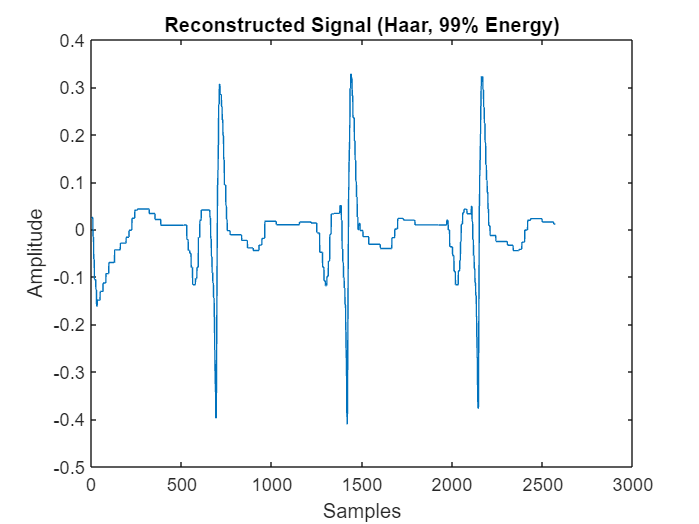


figure;
plot(reconstructed_haar);
title('Reconstructed Signal (Haar, 99% Energy)');
xlabel('Samples');
ylabel('Amplitude');

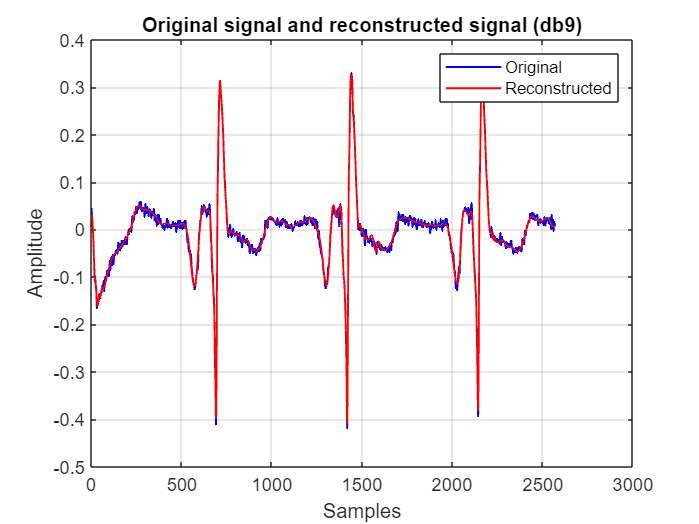

% Plot the reconstructed signals with the original signal (db9)
figure;
plot(aVR, 'b', 'LineWidth', 1); hold on;
plot(reconstructed_db9, 'r', 'LineWidth', 1);
xlabel('Samples'); ylabel('Amplitude');
title('Original signal and reconstructed signal (db9)');
legend('Original', 'Reconstructed');
grid on;

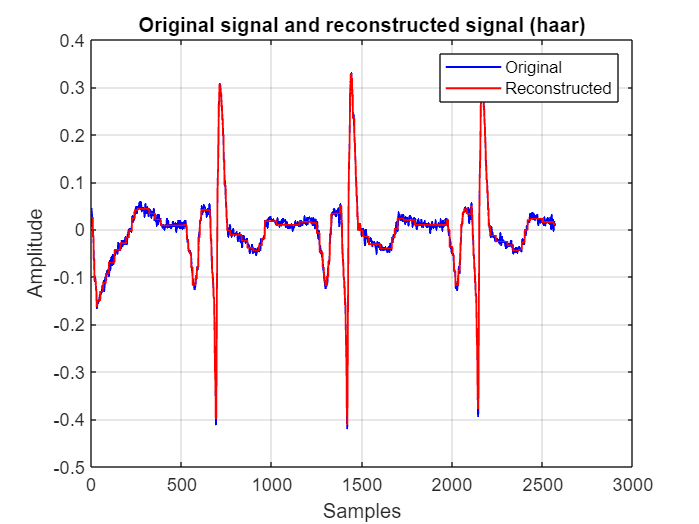

% Plot the reconstructed signals with the original signal (haar)
figure;
plot(aVR, 'b', 'LineWidth', 1); hold on;
plot(reconstructed_haar, 'r', 'LineWidth', 1);
xlabel('Samples'); ylabel('Amplitude');
title('Original signal and reconstructed signal (haar)');
legend('Original', 'Reconstructed');
grid on;